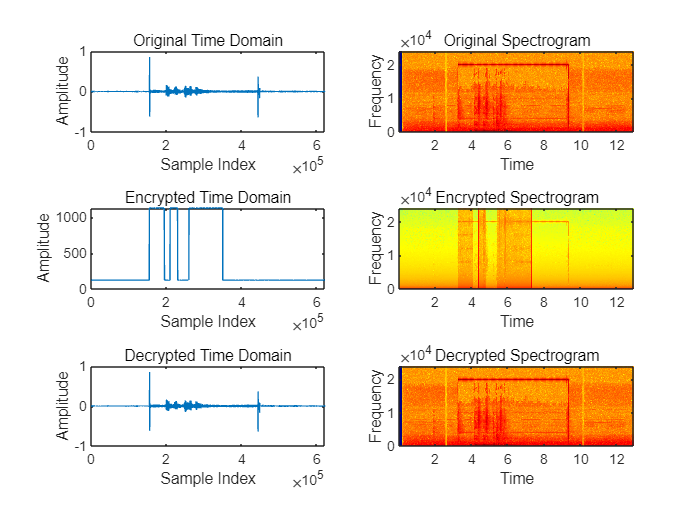

clear all;
clc;
[x, fs] = audioread('tii.wav');
x = x(:, 1); % 双声道分列处理
%x = x(20000:20000*5-1) 
x = ceil(x * 10000); % 全部变为整数
n = length(x);
key1 = 12134234;
key2 = 1234123;
key3 = 56123347;
key4 = 5678151;
x = x + key2;

% 选择三个时间段进行异或
start_indices = [155000, 210000, 260000];
end_indices = [195000, 230000, 350000];

y = x;

for j = 1:numel(start_indices)
    start_idx = start_indices(j);
    end_idx = end_indices(j);

    % 只在选定的时间段内进行异或操作
    y(start_idx:end_idx) = bitxor(x(start_idx:end_idx), key1, 'int32');
end

x = x - key2;
x1 = x / 10000;
sound(x1, fs); % 播放原音频
pause(6.5);

y1 = y / 10000;
sound(y1, fs); % 播放加密音频

z = y;

for j = 1:numel(start_indices)
    start_idx = start_indices(j);
    end_idx = end_indices(j);

    % 只在选定的时间段内进行解密操作
    z(start_idx:end_idx) = bitxor(y(start_idx:end_idx), key1, 'int32');
end

pause(6.5);
z2 = z - key2;
z1 = z2 / 10000;
sound(z1, fs); % 播放解密音频

% 绘制时域波形和频谱
figure;

% 加密前的时域波形
subplot(3, 2, 1);
plot(x1);
title('Original Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

% 加密前的频域波形
subplot(3, 2, 2);
specgram(x1, 512, fs);
title('Original Spectrogram');

% 使用异或进行加密的时域波形
subplot(3, 2, 3);
plot(y1);
title('Encrypted Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

% 使用异或进行加密的频域波形
subplot(3, 2, 4);
specgram(y1, 512, fs);
title('Encrypted Spectrogram');

% 解密后的时域波形
subplot(3, 2, 5);
plot(z1);
title('Decrypted Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

% 解密后的频域波形
subplot(3, 2, 6);
specgram(z1, 512, fs);
title('Decrypted Spectrogram');